# Upsample Audio 

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the audio file and generates the time vector.

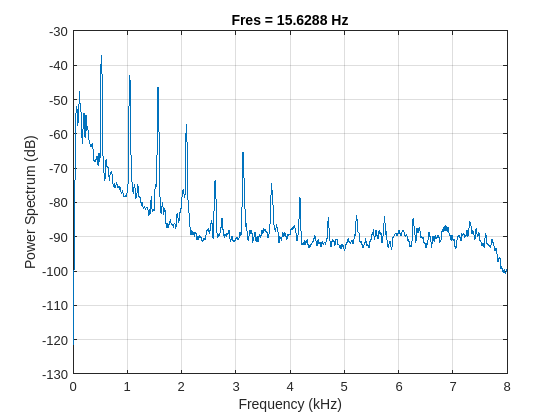

[flute,fs] = audioread("./data/NoisyFlute.wav");
flute = flute(1:7*fs);
n = numel(flute);
t = (0:n-1)';
t = t/fs;
pspectrum(flute, fs)

## Task 1 & 3

In the last lesson, you added a chirp watermark to the flute audio. This was effective, but you still need to be careful not to corrupt any frequencies in your audio. If you wanted to add the watermark to another signal, you'd have to check the spectrum each time and find unused frequencies.

Instead, if you increased the sample rate of the audio first, there would be an unused high-frequency range.

You have seen that it is best to use an anti-imaging filter after upsampling. To see what happens if you don't use the anti-imaging filter with an audio recording, you'll start by using `upsample` on its own.

Because of the imaging, you need a lowpass filter at 8 kHz. The `resample` function includes this filter.

`y` `=` `resample``(``x``,``p``,``q``)`

`p` and `q` are integer resample factors. The output signal `y` has `p``/``q` samples from `x`.

fluteup = upsample(flute, 2)

fluteup =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fluteup = resample(flute, 2, 1)

fluteup =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## Task 2

fsup = fs*2

fsup = 32000

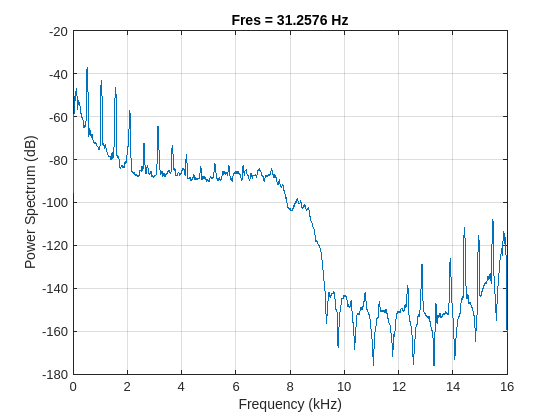

pspectrum(fluteup, fsup)

## Task 4

The frequency content after 8 kHz isn't 0, but it's much smaller with `resample` than with `upsample`.

Now you can create a chirp watermark in the new frequency range. Recall that the syntax to `chirp` is:

`chirp``(``t``,``f0``,``t1``,``f1``)`

tup = (0:numel(fluteup)-1)';
tup = tup/fsup;
wm = chirp(tup, 12000, tup(end), 14000)

wm =     1.0000
   -0.7071
    0.0000
    0.7071
   -1.0000
    0.7071
   -0.0000
   -0.7071
    1.0000
   -0.7072


## Task 5

Since there is very little frequency content in `fluteup` above 8000 Hz, the chirp signal can be very small yet still detectable in the spectrum.

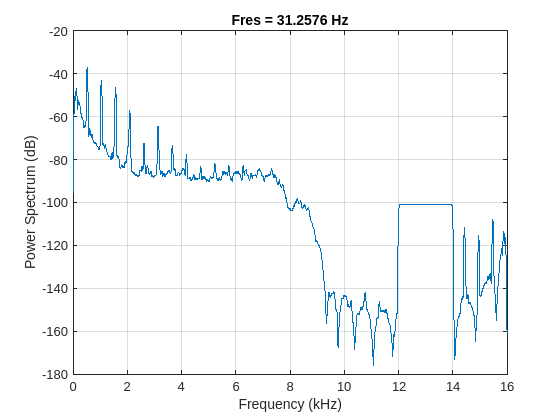

marked = 0.0001*wm + fluteup;
pspectrum(marked, fsup)